# Adiabatic flame temperature (AFT)

## What is it?

The temperature resulting from the **combustion** of a mix of fuels with air under the assumption of no heat loss in a steady process.

Figure 1: AFT from a combustion chamber.

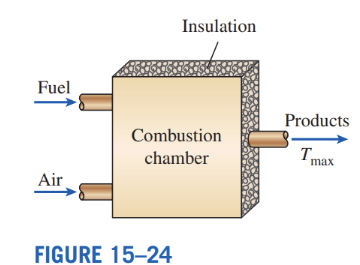

*Taken from [1], pg 780*

In simple terms, **adiabatic** means no heat loss to the surroundings. If the combustion inside a chamber is adiabatic, the assumption is there is no heat transfer to the outside of the chamber.

The main things to consider when calculating the AFT is:

- Fuels and their states (liquid, gas...)

- Amount of air used and its humidity

- Environmental conditions such as temperature and pressure

- Degree of completion of the reaction

The AFT is **maximum** when the proportions of fuels and air is 1:1. In other words, when all the fuels react with all the air available, there is no extra air or fuel components left in the product.

## Why do we care about it?

There are plenty of applications for it, but to name a few:

#### 1. Designing a combustion chamber

The AFT essentially provides the maximum temperature a combustion can ever reach, which is under ideal conditions. This is a useful reference value for the design process of a combustion chamber, for example when choosing the materials or carrying out a simulation.

#### 2. Determining efficiency

When aiming for high temperatures, the AFT can be understood as the "best" temperature the combustion process can reach. This value can be compared to a real flame temperature to evaluate the heat losses and efficiency of the combustion process.

#### 3. Designing thermodynamic cycles

In a cycle that involves combustion chambers, the AFT can be used along with the conditions of the cycle such as power output and efficiency to determine the molar flow and fractions of the combustion chamber (in simpler words, how much fuel is needed to produce certain amount of energy in a power plant design).

## How to calculate it?

The key for calculating AFT is using enthalpy. Considering the combustion chamber as the system, an adiabatic combustion process implies there is no energy loss, for which the enthalpies of the products is equal to the enthalpies of the reactants:

Figure 2: Energy balance of an adiabatic combustion in a chamber

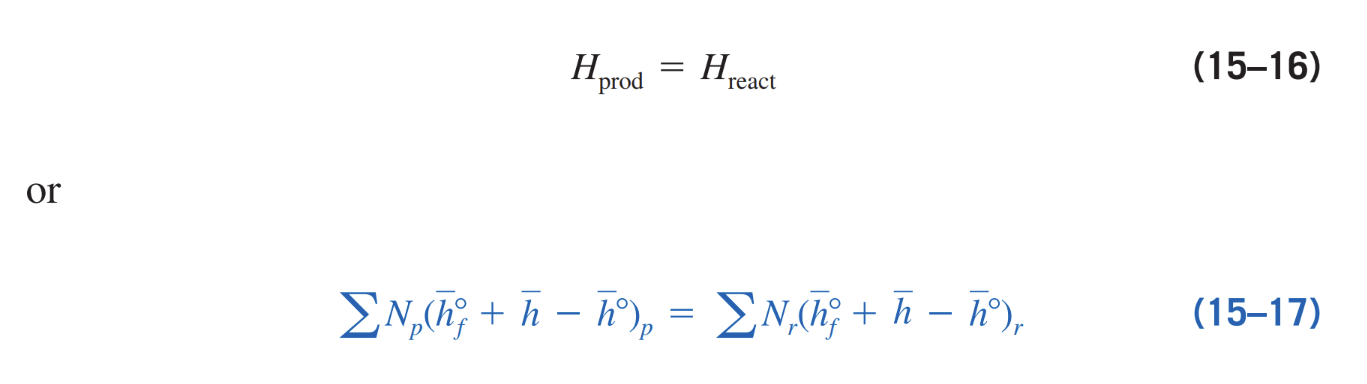

*Taken from [1], pg 780*

In the equations in figure 2, *h°f* is the enthalpy of formation, and *h°* the enthalpy at 298K. *h* is the entalphy at the temperature of the elements before and after the reaction. Consider this entalphy as *hf*.* Adapted from [2].*

Therefore, calculating the AFT can be considered in three steps:

- Determining the moles of the reactants and products

- Obtaining the entalphies for each reactant and product as in figure 2 and solving for *hf*

- Linking *hf *to its corresponding temperature,* tf*

However, step 3 can be particularly challenging since *hf *is different for each product. Therefore, a common technique to calculate it is assuming all products are N2 (since the products will be mostly N2), solving for *hf*, and interpolating from there.

This process is rather tedious and timetaking, but necessary for critical applications. In an attempt to simplify the calculation process, this code provides a function to calculate the AFT: **flametemp()**

# Tutorial for flametemp()

 To use this function, you need the following information:

- Fuels to be used

- State of the fuels

- Fractions of the fuels, if more than one fuel is used

- Proportion of air in the reaction 

- Relative humidity of air

- Air temperature in °C

- Atmospheric pressure in kPa

- Conversion rate of CO2

- Conversion rate of H2O

If you are designing a cycle, you may also need the molar fractions of the products and heat of the combustors, for which you should include:

- Number of combustors

- Efficiency of the cycle

- Power output of the cycle

Below is an example of the syntax:

fuels = ["C2H5OH", "C3H6"];     % Mix of fuels, can be more than one
fuel_state = ["(l)", "(g)"];    % Fuel state (liquid or gas)
fractions = [0.25, 0.75];       % Fuel fractions (proportions in the mix)
real_air = 1.3;                 % Air proportion
phi = 0.85;                     % Relative humidity
air_temp = 40;                  % Air temperature in °C
pressure = 101.325;             % Atmospheric pressure in kPa
xCO2 = 0.7;                     % Conversion of CO2
xH2O = 0.75;                    % Conversion of H2O

% Optional values for cycle information
num_comb = 2;                   % Number of combustors in the cycle
% If including this, also include 2 of the following 3:
eff = 0.4;                      % Efficiency of the cycle
Wnet = 200;                     % Total power output of the cycle, in MW
Qnet = 250;                     % Total heat input of the cycle, in MW


tflame = flametemp(fuels, 'fuel_state', fuel_state, 'fractions', fractions, ...
    'real_air', real_air, 'phi', phi, 'air_temp', air_temp, 'pressure', pressure, ...
    'xCO2', xCO2, 'xH2O', xH2O, 'num_comb', num_comb, 'eff', eff, 'Wnet', Wnet);
disp("AFT: " + tflame)

You may not have all of these values, or you may not be carrying out a critical application. If such, you can skip many of the arguments above. Here is a breakdown:

fuels;      % 1. Fuels to be used (MUST INCLUDE)
fuel_state; % 2. State of the fuels (defaults to gas, "(g)", for all fuels)
fractions;  % 3. Fractions of the fuels (defaults to equal proportions, 1/numel(fuels))
real_air;   % 4. Proportion of air in the reaction (defaults to 1)
phi;        % 5. Relative humidity of air (defaults to 0)
air_temp;   % 6. Air temperature in °C (defaults to 25)
pressure;   % 7. Atmospheric pressure in kPa (defaults to 101.325)
xCO2;       % 8. Conversion rate of CO2 (defaults to 1)
xH2O;       % 9. Conversion rate of H2O (defaults to 1)

% Optional values for cycle information
num_comb;   % 10. Number of combustors in the cycle (defaults to 1)
eff;        % 11. Efficiency of the cycle (Needed for molar flow)
Wnet;       % 12. Total power output of the cycle, in MW (Needed for molar flow)
Qnet;       % 13. Total heat input of the cycle, in MW (Needed for molar flow)

There are also some special options you can activate to print all the process of the code, as well as calculating a more precise AFT by interpolating for enthalpies in a large vector. The syntax is the following:

% printmeall: Debugging - Print all the calculation process
% precise: Calculate precise value for AFT (warning: long calculation times)
tflame = flametemp(fuels, 'fuel_state', fuel_state, 'fractions', fractions, ...
    'real_air', real_air, 'phi', phi, 'air_temp', air_temp, 'pressure', pressure, ...
    'xCO2', xCO2, 'xH2O', xH2O, 'num_comb', num_comb, 'eff', eff, 'Wnet', Wnet, ...
    'printmeall', true, 'precise', true);
disp("Precise AFT: " + tflame)

These options are both deactivated (false) by default.

#### Credits

Author: Jorge Porras (2025)

Adapted from:

- Cengel, Y. (2015). *Thermodynamics: An Engineering Approach.* McGraw Hill: 8th Ed. 

- Robayo, D (2024). *Termoquímica de la Combustion* (Lecture Notes). Universidad de La Sabana.